# Matlab Implementation

## **Filtering algorithm**

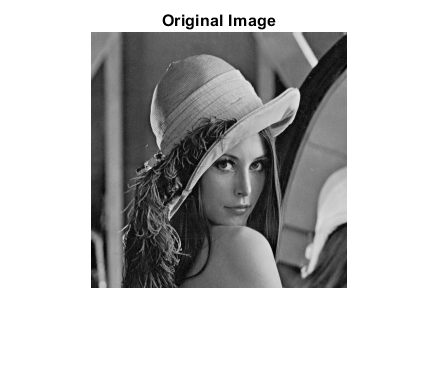

clc;
close all;
clear all;
original_im = imread('C:\Users\hirun\OneDrive\Desktop\EN3030 - Circuits and Systems Design\Processor Design Project\lena.tif'); %Open the grayscale image
im_double = im2double(original_im);
[M, N] = size(original_im); %M = number of rows N = number of columns
half_width = 1; %Half width of the Kernel
sigma = 2/3; %Sigma value that determines the extent of smoothing
[x y] = meshgrid([-half_width:half_width]' , [-half_width:half_width]');
guassian = exp(-(x.^2 + y.^2)/(2*sigma^2))/(2*pi*sigma^2); %Defining Gaussian Kernel
filtered_im = zeros(M,N);
for i = 1+half_width : M-half_width
    for j = 1+half_width : N-half_width
        filtered_im(i,j) = sum(sum(guassian.*im_double(i-half_width:i+half_width,j-half_width:j+half_width)));
    end
end
filtered_Im_funct = imfilter(original_im, guassian,'conv');
%I2 = filter2(original_im,guassian);
%I3 = conv2(original_im,guassian);
figure(1);
imshow(original_im);
title('Original Image');

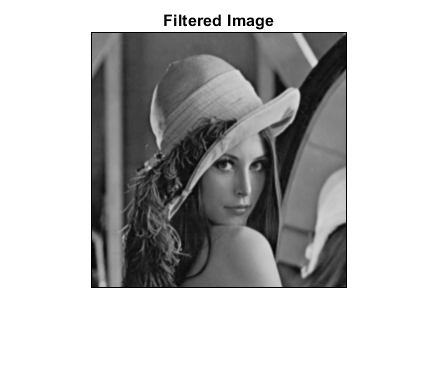

figure(2);
imshow(filtered_im);
title('Filtered Image');

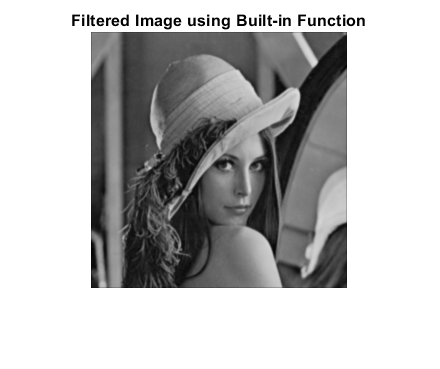

figure(3);
imshow(filtered_Im_funct);
title('Filtered Image using Built-in Function');

imwrite(filtered_im,'C:\Users\hirun\OneDrive\Desktop\EN3030 - Circuits and Systems Design\Processor Design Project\lena_filtered.tif');

## **Down sampling Algorithm**

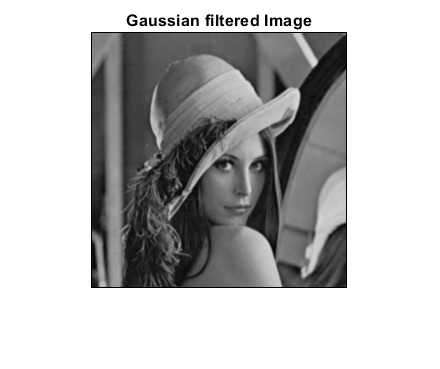

clc;
close all;
clear all;
filtered_im = imread('C:\Users\hirun\OneDrive\Desktop\EN3030 - Circuits and Systems Design\Processor Design Project\lena_filtered.tif'); % Open the filtered grayscale image
im_double = im2double(filtered_im);
[M N] = size(filtered_im); %M = number of rows N = number of columns
%% Down Sampling Code
M_downsampled = 128;
N_downsampled = 128;
Downsampling_Factor = 2;
Downsampled_im = zeros(M_downsampled,N_downsampled);
for i=1:M_downsampled
    for j=1:N_downsampled
        Downsampled_im(i,j) = sum(filtered_im(Downsampling_Factor*i, Downsampling_Factor*j-1:Downsampling_Factor*j))/2;
    end
end
Downsampled_im = uint8(Downsampled_im);
%% Display Results
figure(1);
imshow(filtered_im);
title('Gaussian filtered Image');

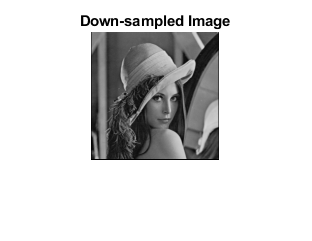

figure(2);
imshow(Downsampled_im);
title('Down-sampled Image');

%% Saving the Results
imwrite(Downsampled_im,'C:\Users\hirun\OneDrive\Desktop\EN3030 - Circuits and Systems Design\Processor Design Project\lena_downsampled.tif');